# This Script Calculates Optical Surface Deformation

Input from PTC CREO Simulate simulation is required

clear all
clc

%% Data Import
try
    lastLocation_ = readlines("lastLocation.txt");
    lastLocation = lastLocation_{1};
catch
    lastLocation = defaultSimResFolder;
end

[creoResultsFile, creoResultsLocation] = uigetfile(fullfile(lastLocation,'*.csv'),...
 "Provide Simulation Results File");
writelines(creoResultsLocation, 'lastLocation.txt')

[TS1, TS2] = importCreoResults(fullfile(creoResultsLocation, creoResultsFile));

Parsed 507 valid rows, discarded 30 bad rows.


head(TS1, 5), head(TS2, 5)

    PointId        X           Y            Z            dX             dY            dZ   
    ________    _______    __________    ________    ___________    ___________    ________

    "PNT0"            0    6.1232e-21           0    -3.5639e-06     0.00012117    0.050048
    "PNT1"            0        1.9099    0.050633     -3.894e-06    -0.00059563    0.049956
    "PNT10"     -3.8197     2.339e-16     0.20301      0.0014369     0.00011608     0.05012
    "PNT100"    -11.459    7.0168e-16      1.8596      0.0046084     6.4089e-05    0.050704
    "PNT101"    -11.285       -1.9899      1.8596      0.0045678     0.00086407    0.050863

    PointId    X    Y    Z    dX

% Script Parameters

surfaceUnderTest = "S1";
waveLength = 0.632; % microns
nZerTerms = 20;
defaultSimResFolder = 'D:\Creo_Simulations';
sagEq = @(rho, S) (rho.^2/S.RR)./(1+sqrt(1-(1+S.K).*(rho./S.RR).^2)) ...
                     + S.A(2).*rho.^2 + S.A(4).*rho.^4 ...
                     + S.A(6).*rho.^6 + S.A(8).*rho.^8 ...
                     + S.A(10).*rho.^10 + S.A(12).*rho.^12 + S.A(14).*rho.^14;
SimCS2OpticsCS = ([1 0 0; ...
                   0 1 0; ...
                   0 0 1;]);

% Lens Parameters

S1.A = zeros(14,1);
S1.A(4) = (-5.154e-6);
S1.A(6) = (-2.450e-8);
S1.A(8) = (-5.260e-11);
S1.A(10) = (-6.692e-13);
S1.RR = 27.321;
S1.K = 0;

S2.A = zeros(14,1);
S2.A(4) = (-5.154e-6);
S2.A(6) = (-2.450e-8);
S2.A(8) = (-5.260e-11);
S2.A(10) = (-6.692e-13);
S2.RR = 27.321;
S2.K = 0;

switch surfaceUnderTest
    case 'S1'
        S = S1;
        TS = TS1;
    case 'S2'
        S = S2;
        TS = TS2;
end

## Best-fit rigid body motion (6DOF) from P -> Q

% Q = R*P + t

% P : Nx3 original coordinates [X Y Z]
% U : Nx3 displacements [dX dY dZ]
% Q : Nx3 displaced locations, including rigid body and deformation

S.P = [TS.X TS.Y TS.Z];
S.U = [TS.dX TS.dY TS.dZ];

S.Q = S.P + S.U; % new points position: rigid body + deformation

[S.R_rb, S.t_rb] = bestFitRigidTransform(S.P, S.Q);

S.Qrigid = (S.R_rb * (S.P).' + S.t_rb);    % new points position: rigid body only
S.Qrigid = (S.Qrigid).';         % Nx3

S.Q_noRigid = S.Q - (S.Qrigid - S.P); % new points position: deformation only
S.dZ = S.Q_noRigid(:,3) - S.P(:,3); % rigid body free axial displacement

S.tiltY = asin(-S.R_rb(3,1)); % rotation about Y (pitch)
S.tiltX   = atan2(S.R_rb(3,2), S.R_rb(3,3));         % rotation about X (roll)
S.deccenter = sqrt(S.t_rb(1:end-1)'*S.t_rb(1:end-1));
S.defocus = S.t_rb(3);

fprintf("Rigid motion:\n Deccenter = %2.f [microns],\n Defocus = %.2f [microns],\n Tilt = %.2f [mRad]\n", ...
                        S.deccenter*1000, S.defocus*1000, sqrt(S.tiltX^2+S.tiltY^2)*1000);

Rigid motion:
 Deccenter =  0 [microns],
 Defocus = 50.55 [microns],
 Tilt = 0.08 [mRad]


% Axial displacement
% dZ_tot = dZ - dSag
% dSag = Sag(X/Y_old) - Sag(X/Y_new)

TS.Xnew = S.Q_noRigid(:,1);
TS.Ynew = S.Q_noRigid(:,2);
TS.Znew = S.Q_noRigid(:,3);

[TS.theta_new, TS.r_new] = cart2pol(TS.Xnew, TS.Ynew);
[TS.theta, TS.r] = cart2pol(TS.X, TS.Y);

% Calculating deformation of sag = total sag change - 
S.dSag = sagEq(TS.r_new, S) - sagEq(TS.r, S);
TS.dZ_tot = S.dZ - S.dSag; % Rigid body free sag-shift

S.dZ_PV = max(TS.dZ_tot) - min(TS.dZ_tot);
S.dZ_rms = rms(TS.dZ_tot);

## Zernike fit - Zemax Fringe Notation


$$\delta Z_{fit} = M_{zernike} \cdot w_{zernike} \\
M \text{ - Zernike fringe design matrix} \\
w \text{ - Zernike weights}$$


S.CA = max(TS.r_new);
S.rho = TS.r_new/S.CA;
S.M_zernike = zemaxFringeMatrix(S.rho, TS.theta_new, nZerTerms);
S.w_zernike = S.M_zernike \ TS.dZ_tot;

TS.dZ_fit = S.M_zernike*S.w_zernike;
S.fit_rms = sqrt(mean((TS.dZ_tot - TS.dZ_fit).^2));

run zemaxFringeTermsTable_generator;
S.ZemaxFringeTerms = ZemaxFringeTerms;

S.ZemaxFringeTerms.Value_mm = S.w_zernike;

% General Values
fprintf("General Sag distortion:\n P-V dZ = %.2f [waves],\n RMS dZ = %.2f [waves],\n", S.dZ_PV*1000/waveLength, S.dZ_rms*1000/waveLength);

General Sag distortion:
 P-V dZ = 4.45 [waves],
 RMS dZ = 2.36 [waves],


% Zernike Report
fprintf("Zernike fringe fit: terms=%d, RMS residual=%.2f [waves], wave=%.3f [nm]\n", nZerTerms, S.fit_rms*1e3/waveLength, waveLength*1000);

Zernike fringe fit: terms=20, RMS residual=0.08 [waves], wave=632.000 [nm]


fprintf("Terms normilized for radius of: %.1f[mm]\n", S.CA);

Terms normilized for radius of: 13.4[mm]



head(S.ZemaxFringeTerms, 20)

    #                 Name                           Formula               Value_mm  
    __    _____________________________    ___________________________    ___________

     1    {'Piston'                   }    {'1'                      }      0.0010675
     2    {'Tilt X'                   }    {'ρ cosθ'                 }     8.8566e-08
     3    {'Tilt Y'                   }    {'ρ sinθ'                 }     9.4961e-06
     4    {'Defocus'                  }    {'2ρ² − 1'                }      0.0014078
     5    {'Astigmatism 45°'          }    {'ρ² sin(2θ)'             }    -4.4647e-06
     6    {'Astigmatism 0°'           }    {'ρ² cos(2θ)'             }    -1.1845e-05
     7    {'Coma Y'                   }    {'(3ρ³ − 2ρ) sinθ'        }    -0.00013492
     8    {'Coma X'                   }    {'(3ρ³ − 2ρ) cosθ'        }    -1.3604e-06
   

## Plot Results

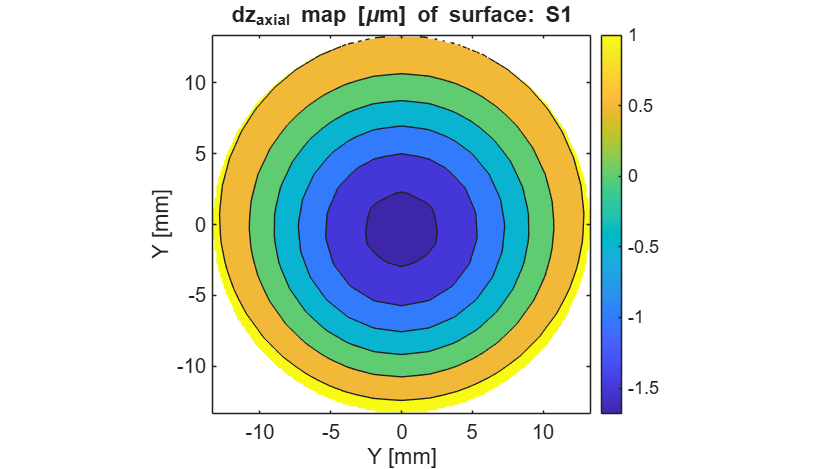

dZ_fit_noRB = S.M_zernike*[0;S.w_zernike(2:end)];

[Xg, Yg] = meshgrid(linspace(min(TS.Xnew), max(TS.Xnew), 200), ...
                    linspace(min(TS.Ynew), max(TS.Ynew), 200));
Zg = griddata(TS.X, TS.Y, dZ_fit_noRB, Xg, Yg);

figure(Units="normalized", Position=[0,0, 0.8, 0.8])
contourf(Xg, Yg, Zg*1000);
set(gca, 'YDir', 'normal');
set(gca, 'Fontsize', 15)
xlabel('Y [mm]');
ylabel('Y [mm]');
title(sprintf('dz_{axial} map [\\mum] of surface: %s', surfaceUnderTest));
axis equal
colorbar;